## Risk Assessment using a Markov chain 

**Background**

Suppose that a car insurance company has classified clients in five categories of risk.

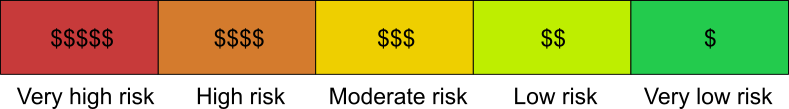

*Risk categories. High risk clients pay higher premiums because they are more likely to require a payout on a claim.*

Each year, the risk of a client is reassessed. Clients will be moved between categories based on their history. For example

- Being at fault in an accident will move a client into a higher risk category

- Having a year without an incident will move the client into a lower risk category

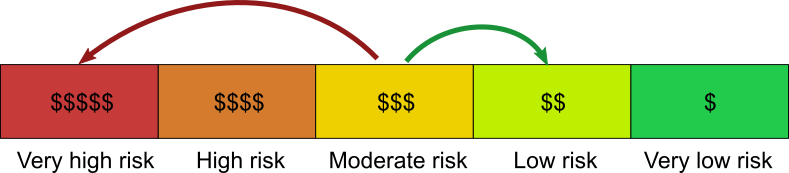

*Twp possible transitions of clients between categories.*

A Markov chain can be used to model how the pool of clients will change based on a the history of how clients have moved between categories. The client history is represented as a probability (over 1 year) that a client will move into another category or stay in the same category.

The goal of the model is to determine how the distribution of clients in different risk categories will change in the future based on the history of how clients have moved between risk categories in the past.

**Transitions**

Let the fraction of clients in a given category be modeled by

    
$$\mathbf{r} = \left( \matrix{ r_1 \cr r_2 \cr r_3 \cr r_4 \cr r_5 } \right)$$


Each variable $r_i$ represents the fraction of clients in each risk category (with all clients $= \sum_i r_i = 1$). The lowest risk being represented by $r_5$ and $r_1$ indicating very high risk. In each year, a client has a probability that they will move into another category or remain in that same cateogry. 

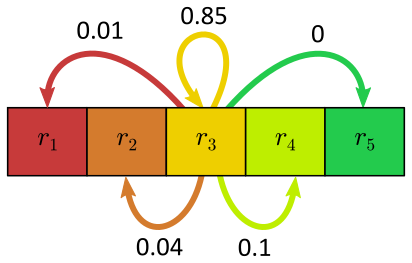

*Likelihoods for *$r_3$* clients. On average 85% remain in *$r_3$ each year. A few move into other categories. However, 0% will move into $r_5$, since they will have to pass through the low risk ($r_4$) category first.

Notice that the total probability of transitions out of $r_3$ are equal to 1. These transitions are just one set of probabilities. In fact, there are 5 sets of transitions out of each category.

**Transition matrix**

The* transition matrix *$\mathbf{P}$ determines estimates how clients will move between all 5 categories each year. To find the new classication of the clients after one year, multiply the transition matrix by the current state vector $\mathbf{r}$:

    
$$\mathbf{r}_{new} = \mathbf{P} \mathbf{r}$$


 The transition matrix is the heart of a Markov chain model. In general, the transition probabilities would be estimated based on historical data. $\mathbf{P}$ has the form

P = sym("p",[5 5])

$$P = \left(\begin{array}{ccccc} p_{1,1} & p_{1,2} & p_{1,3} & p_{1,4} & p_{1,5}\\ p_{2,1} & p_{2,2} & p_{2,3} & p_{2,4} & p_{2,5}\\ p_{3,1} & p_{3,2} & p_{3,3} & p_{3,4} & p_{3,5}\\ p_{4,1} & p_{4,2} & p_{4,3} & p_{4,4} & p_{4,5}\\ p_{5,1} & p_{5,2} & p_{5,3} & p_{5,4} & p_{5,5} \end{array}\right)$$

Each column determines the probabilities of transitioning out of one risk group and into another. For example, the third column determines the likelihood of transitions out of the $r_3$ client class:

- $p_{1,3}$ = probability of transition $r_3 \rightarrow r_1$

- $p_{2,3}$ = probability of transition $r_3 \rightarrow r_2$

- $p_{3,3}$ = probability of transition $r_3 \rightarrow r_3$ (staying in the same category)

- $p_{4,3}$ = probability of transition $r_3 \rightarrow r_4$

- $p_{5,3}$ = probability of transition $r_5 \rightarrow r_4$

This works because the matrix-vector multiplication $\mathbf{r}_{new} = \mathbf{P} \mathbf{r}$ yields:

r = sym("r",[5,1]);
rnew = P*r

$$rnew = \left(\begin{array}{c} p_{1,1}\,r_{1}+p_{1,2}\,r_{2}+p_{1,3}\,r_{3}+p_{1,4}\,r_{4}+p_{1,5}\,r_{5}\\ p_{2,1}\,r_{1}+p_{2,2}\,r_{2}+p_{2,3}\,r_{3}+p_{2,4}\,r_{4}+p_{2,5}\,r_{5}\\ p_{3,1}\,r_{1}+p_{3,2}\,r_{2}+p_{3,3}\,r_{3}+p_{3,4}\,r_{4}+p_{3,5}\,r_{5}\\ p_{4,1}\,r_{1}+p_{4,2}\,r_{2}+p_{4,3}\,r_{3}+p_{4,4}\,r_{4}+p_{4,5}\,r_{5}\\ p_{5,1}\,r_{1}+p_{5,2}\,r_{2}+p_{5,3}\,r_{3}+p_{5,4}\,r_{4}+p_{5,5}\,r_{5} \end{array}\right)$$

In this result, the first row sums the probabilities of moving into $r_1$ ($p_{1,i}$), multiplied by the current fraction of clients in each category, $r_i$. That sum yields the total number of clients in the $r_1$ category (and similarly for the others).

**Constructing a transition matrix**

To implement the specific transitions shown above for the $r_3$ group, we change the third colum to the transition values. 

*Likelihoods for *$r_3$* clients.*

P(:,3) = [0.01 0.04 0.85 0.1 0]

$$P = \left(\begin{array}{ccccc} p_{1,1} & p_{1,2} & \frac{1}{100} & p_{1,4} & p_{1,5}\\ p_{2,1} & p_{2,2} & \frac{1}{25} & p_{2,4} & p_{2,5}\\ p_{3,1} & p_{3,2} & \frac{17}{20} & p_{3,4} & p_{3,5}\\ p_{4,1} & p_{4,2} & \frac{1}{10} & p_{4,4} & p_{4,5}\\ p_{5,1} & p_{5,2} & 0 & p_{5,4} & p_{5,5} \end{array}\right)$$

  **Task. ** Use the transitions shown in the image below to set the transitions out of $r_1$.

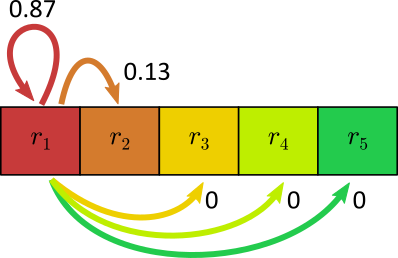

*Likelihoods for *$r_1$* clients. The only path out is to be moved into the high risk category.*

  **Pro-tip**: Set the column of the matrix using `P(:,i) = [values]`. The "`:`" operator indicates that all rows will be selected. The index `i `determines the column index.

P(:,1) = [0.87 0.13 0 0 0]

$$P = \left(\begin{array}{ccccc} \frac{87}{100} & p_{1,2} & \frac{1}{100} & p_{1,4} & p_{1,5}\\ \frac{13}{100} & p_{2,2} & \frac{1}{25} & p_{2,4} & p_{2,5}\\ 0 & p_{3,2} & \frac{17}{20} & p_{3,4} & p_{3,5}\\ 0 & p_{4,2} & \frac{1}{10} & p_{4,4} & p_{4,5}\\ 0 & p_{5,2} & 0 & p_{5,4} & p_{5,5} \end{array}\right)$$

The rest of the transitions have been filled in below. 

P = [0.87 0.05 0.01 0.01 0.01;
     0.13 0.83 0.04 0.02 0.01;
     0.00 0.12 0.85 0.05 0.02;
     0.00 0.00 0.10 0.90 0.03;
     0.00 0.00 0.00 0.02 0.93]

P =     0.8700    0.0500    0.0100    0.0100    0.0100
    0.1300    0.8300    0.0400    0.0200    0.0100
         0    0.1200    0.8500    0.0500    0.0200
         0         0    0.1000    0.9000    0.0300
         0         0         0    0.0200    0.9300


  **Try. **The transition matrix can be visualized by a digraph. Run this section to visualize the transitions.

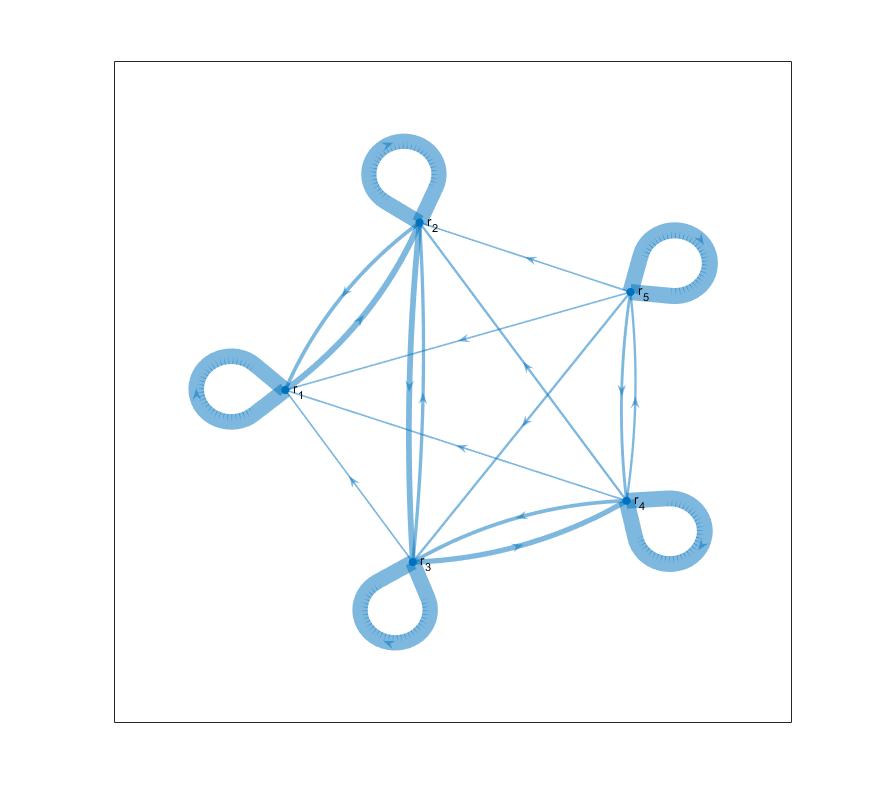

figure('position',[1,1,700,650])
G = digraph(P',["r_1","r_2","r_3","r_4","r_5"]);
plot(G,"linewidth",10*sqrt(G.Edges.Weight))

**Applying a transition matrix**

Suppose that, initially, the clients are equally distributed in all categories:

r = [0.2 0.2 0.2 0.2 0.2]' % Distribution of clients: 20% in each category

r =     0.2000
    0.2000
    0.2000
    0.2000
    0.2000


  **Task. **After one year, what will the new client classification be? Use matrix multiplication.

r1 = P*r

r_1year =     0.1900
    0.2060
    0.2080
    0.2060
    0.1900


Repeated applications of the transition matrix will yield distributions of clients' risk categories. 

  **Task. **After 10 years, what wil be the risk distribution?

r10 = P^10*r

r_10year =     0.1238
    0.2080
    0.3119
    0.3146
    0.0417


  **Task. **After 100 years, what wil the risk distribution be?

r100 = P^100*r

r_100year =     0.1300
    0.2051
    0.2763
    0.3022
    0.0863


 **Reflect**

- Which categories end up with the largest share of clients? Which have the least?

- From a business standpoint, is this long-term distribution of clients desirable?

- Try starting with a different initial set of clients, $\mathbf{r}$. Does the resulting distribution change after many applications of the matrix?

**Eigen analysis**

The long-term behavior of a Markov chain model can be understood in terms of its eigenvalues and eigenvectors. A non-defective square matrix can diagonlized by computing its eigen decomposition:

    $\mathbf{P} =\mathbf{V \Lambda V}^{-1} $.

This implies that for the update after one year:

    $\mathbf{r}_{(1)} = \mathbf{V \Lambda V}^{-1} \mathbf{r}$.

To compute the state distribution after $n$ years, multiply by the transition matrix $n$ times:

    
$$\begin{array} {rl}
\mathbf{r}_{(n)} &= ( \mathbf{V \Lambda V}^{-1} )^n\mathbf{r}
\\
  &= (\mathbf{V \Lambda V}^{-1} )(\mathbf{V \Lambda V}^{-1} )\ldots (\mathbf{V \Lambda V}^{-1} )\mathbf{r}
\\
  &= \mathbf{V \Lambda}^n \mathbf {V}^{-1}  \mathbf{r}
\end{array}$$


** Exercise**. Compute the eigen decomposition of $\mathbf{P}$ and use it to compute the risk distribution $\mathbf{r}$ after 100 years.

r = [0.2 0.2 0.2 0.2 0.2]' % Distribution of clients: 20% in each category

r =     0.2000
    0.2000
    0.2000
    0.2000
    0.2000


% Compute r(100) here
[V,D] = eig(P)

V =     0.1584    0.0961   -0.2687    0.2313   -0.1712
   -0.4659   -0.1106   -0.4239    0.2112   -0.2874
    0.7295   -0.6165   -0.5711   -0.1169   -0.2996
   -0.4724    0.7624   -0.6246   -0.8091   -0.1262
    0.0503   -0.1314   -0.1785    0.4834    0.8845


D =     0.7424         0         0         0         0
         0    0.8140         0         0         0
         0         0    1.0000         0         0
         0         0         0    0.8965         0
         0         0         0         0    0.9271


r100 = V*D^100*inv(V)*r

r100 =     0.1300
    0.2051
    0.2763
    0.3022
    0.0864


**Limit behavior**

Understanding this limiting behavior can be accomplished more directly by examining the eigenvalues contained in$\mathbf{\Lambda}$. Notice that for the transfer matrix, the eigenvalues have the property that $\lambda \leq1$:

D

D =     0.7424         0         0         0         0
         0    0.8140         0         0         0
         0         0    1.0000         0         0
         0         0         0    0.8965         0
         0         0         0         0    0.9271


Using this property, you will find that, in the limit:

    
$$\lim_{n\rightarrow \infty} \mathbf{\Lambda}^n = 
\left(\begin{array}{ccccc}
0 & 0 & 0 & 0 & 0\\
0 & 0 & 0 & 0 & 0\\
0 & 0 & 1 & 0 & 0\\
0 & 0 & 0 & 0 & 0\\
0 & 0 & 0 & 0 & 0
\end{array}\right)$$


% This defines the limit of the diagonal matrix
Dinf = zeros(5,5);
Dinf(3,3) = 1

Dinf =      0     0     0     0     0
     0     0     0     0     0
     0     0     1     0     0
     0     0     0     0     0
     0     0     0     0     0


  **Task. **Compute the limiting behavior as $n \to \infty$ of the system:

    
$$\begin{array} {rl}
\mathbf{r}_{(n)} = \mathbf{P}^{n}  \mathbf{r}
\end{array}$$
    

by computing the matrix $\mathbf{P}_\infty$ which satisfies

    $\mathbf{P}_\infty =   \lim_{n\rightarrow \infty} \mathbf{V \Lambda}^n \mathbf {V}^{-1}$.    

Pinf = V*Dlim*inv(V)

Pinf =     0.1300    0.1300    0.1300    0.1300    0.1300
    0.2051    0.2051    0.2051    0.2051    0.2051
    0.2763    0.2763    0.2763    0.2763    0.2763
    0.3022    0.3022    0.3022    0.3022    0.3022
    0.0864    0.0864    0.0864    0.0864    0.0864


  **Task. **Compute the limit distribution

    
$$\begin{array} {rl}
\mathbf{r}_{(\infty)} = \mathbf{P}^{\infty}  \mathbf{r}
\end{array}$$
    

and plot it as a bar graph using the [`bar`](https://www.mathworks.com/help/matlab/ref/bar.html) function.

rinf = Pinf*r

rinf =     0.1300
    0.2051
    0.2763
    0.3022
    0.0864


This code plots the result as a bar graph using the [`bar`](https://www.mathworks.com/help/matlab/ref/bar.html) function.

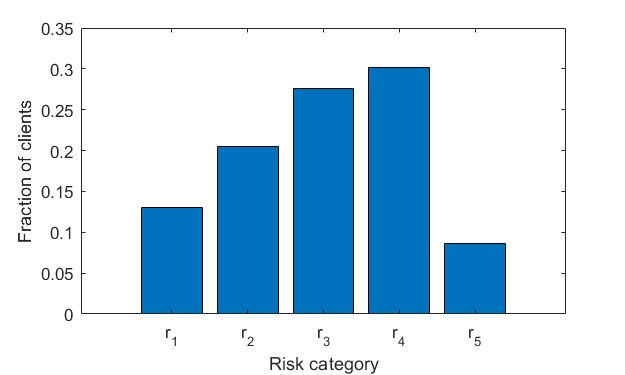

figure('position',[1,1,500,300])
bar(rinf)
set(gca,"xticklabel","r_" + strsplit(num2str(1:5)))
ylabel("Fraction of clients")
xlabel("Risk category")

 **Reflect**

- What relationship is there between the starting distribution $\mathbf{r}$ and the limit distribution? The form of the matrix $\mathbf{P}_{\infty}$ can be used to identify the relationship.

- What is the business significance of $\mathbf{r}_\infty$?